clc
clear

% Import the data from .csv file
[t, toy, p, Ws1, Wd1, T1, Ws2, Wd2, T2, Ws3, Wd3, T3] = ...
    importfile('cex4WindDataInterpolated.csv');

## Fit an ARMA model to p

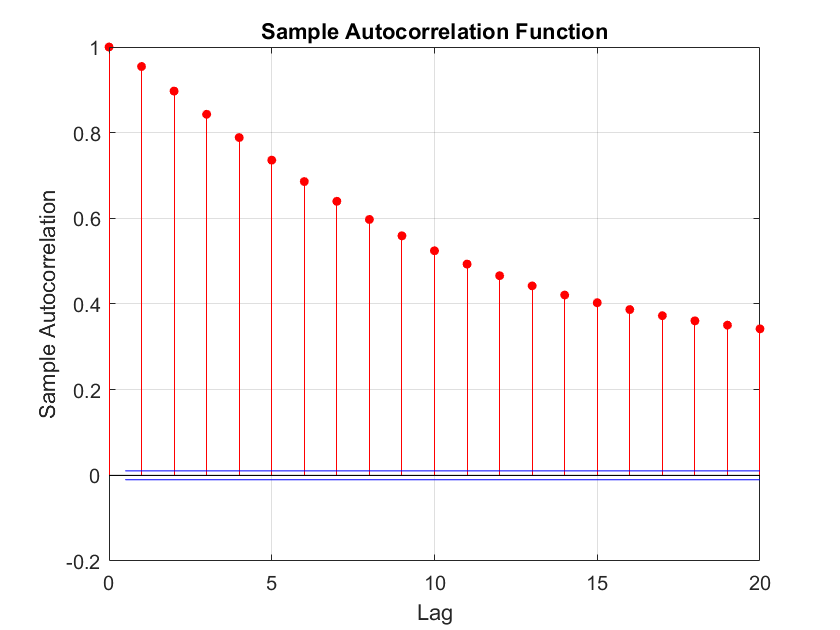

% Plot ACF and PACF
figure(1)
autocorr(p)

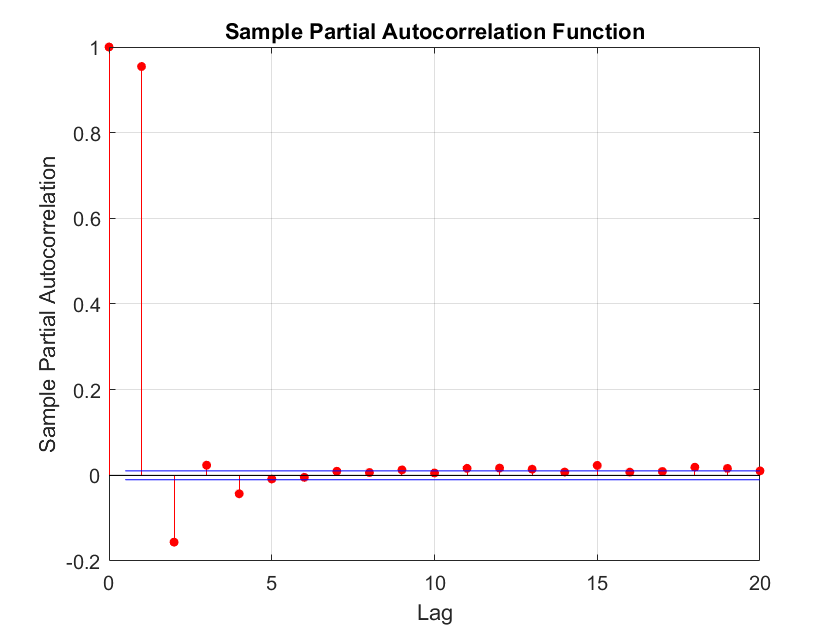


figure(2)
parcorr(p)

**The suggested model is clearly autoregressive. 4 lags look significant.**

% Test an AR(4)
Md1 = arima(4,0,0);
EstMd1 = estimate(Md1,p)

 
    ARIMA(4,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.26336       0.017961        14.662      1.1209e-48
    AR{1}          1.1075      0.0033734        328.31               0
    AR{2}        -0.18942      0.0045974       -41.201               0
    AR{3}        0.071078      0.0050572        14.055      7.1863e-45
    AR{4}       -0.042773      0.0035681       -11.988      4.1174e-33
    Variance       2.6148       0.010561        247.58               0



EstMd1 =   arima with properties:

     Description: "ARIMA(4,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 4
               D: 0
               Q: 0
        Constant: 0.26336
              AR: {1.1075 -0.189417 0.071078 -0.0427732} at lags [1 2 3 4]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 2.61481

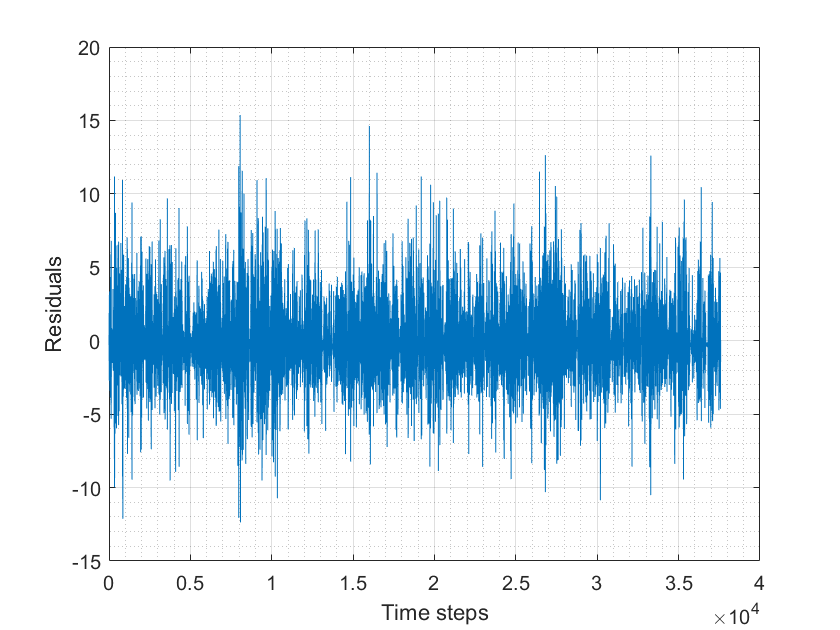

% Compute the residuals
[res1, R] = infer(EstMd1,p);
plot(res1)
grid on; grid minor;
xlabel('Time steps')
ylabel('Residuals')


% Ljung-Box test
[h,pvalues]=lbqtest(res1,'lags',[1,2,3,4,5,6,7,8,9,10])

h = 1×10 logical array
   0   0   0   0   0   0   0   0   0   0


pvalues =     0.9454    0.9976    0.9988    0.7649    0.5994    0.4274    0.3950    0.2092    0.2551    0.0834


% Validation of the hypothesis that the residuals are not correlated

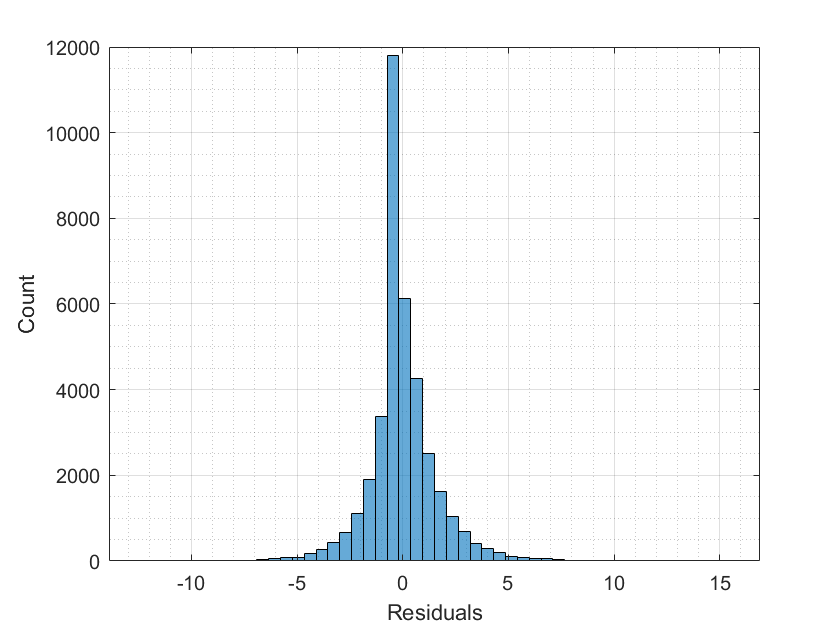

%Histogram of residuals
histogram(res1,50)
grid on; grid minor;
xlabel('Residuals')
ylabel('Count')

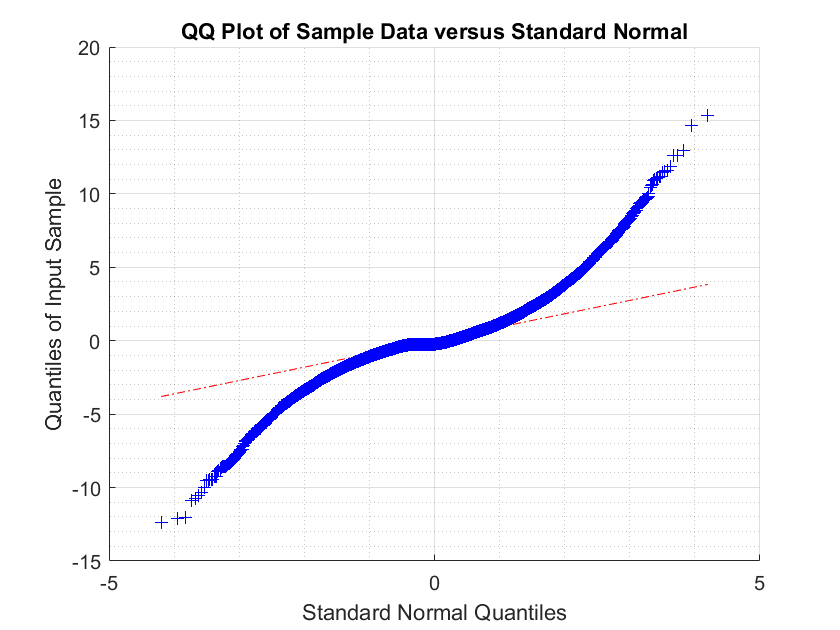


%QQ plot
qqplot(res1)
grid on; grid minor;

% Sign test
count=0;
for i=1:length(res1)-1
    if sign(res1(i)) == sign(res1(i+1))
        count = count+1;
    end
end
percent_sign_change = count/length(res1)

percent_sign_change = 0.6101


%The number of sign changes is not between 40 and 60%
%This is not white noise

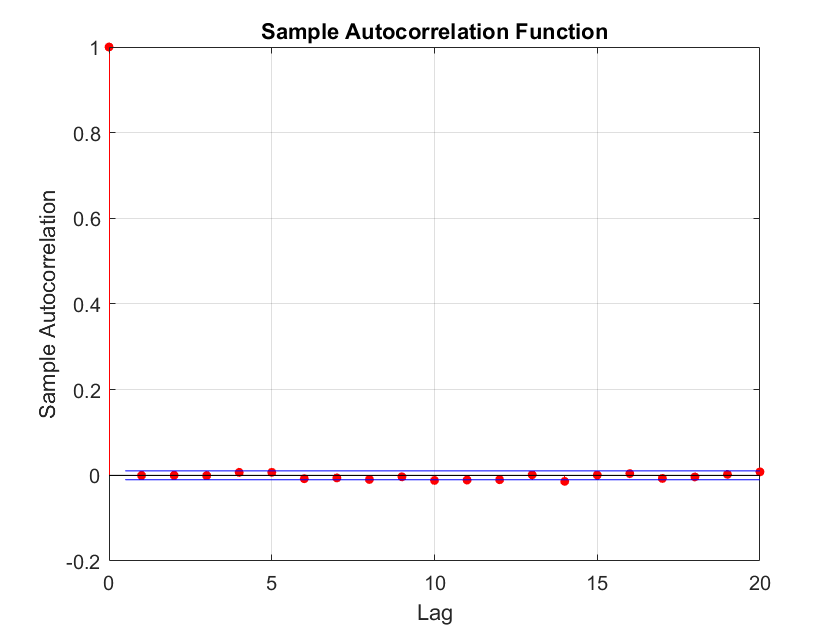

% ACF and PACF of the residuals
autocorr(res1)

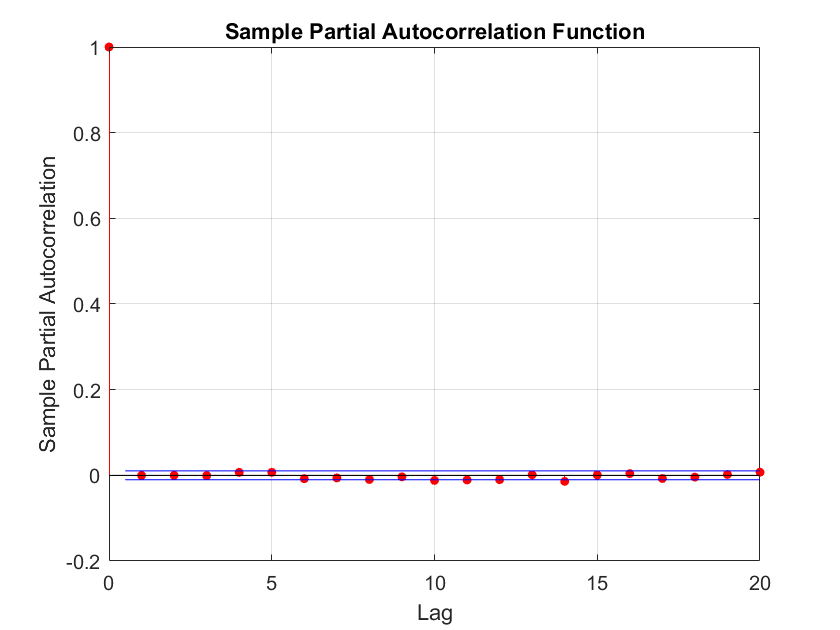

parcorr(res1)

**From the QQ plot and the sign test we can assess that the residuals are not white noise. However, there is no more linear relation to be found as shown in the ACF and PACF of the residuals.**

**The shape of the QQ plot indicates the residuals have more extreme values than a normal distribution would assume.**

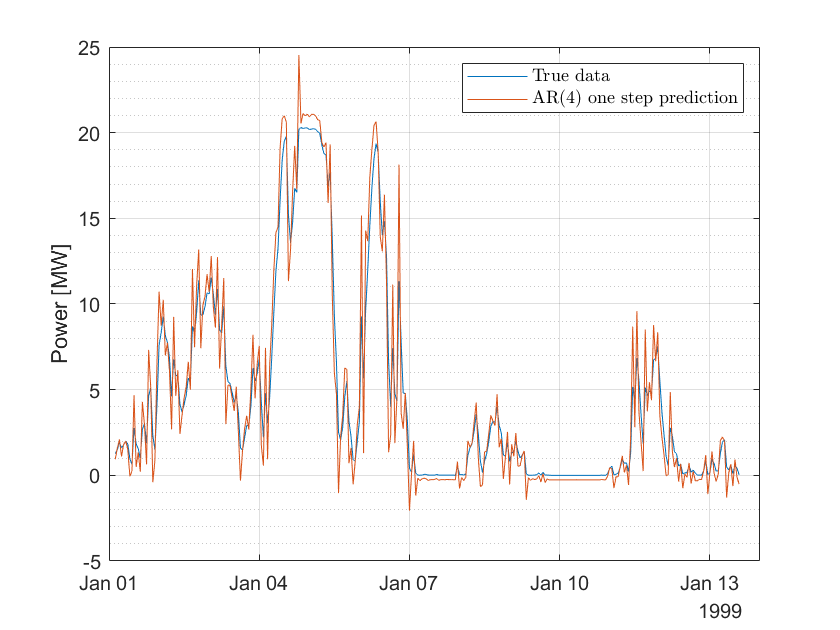

% Plot the predictions
t_plot = 300;
predictions = p(1:t_plot) + res1(1:t_plot);
plot(t(1:t_plot),p(1:t_plot),t(1:t_plot),predictions(1:t_plot))
grid on; grid minor;
ylabel('Power [MW]')
legend({'True data','AR(4) one step prediction'},"Interpreter","latex")

**We could have expected diurnal variations. This can be assessed by the ACF and PACF at lag 24 and 48. Let's get the ACF and PACF of the residuals for higher lags.**

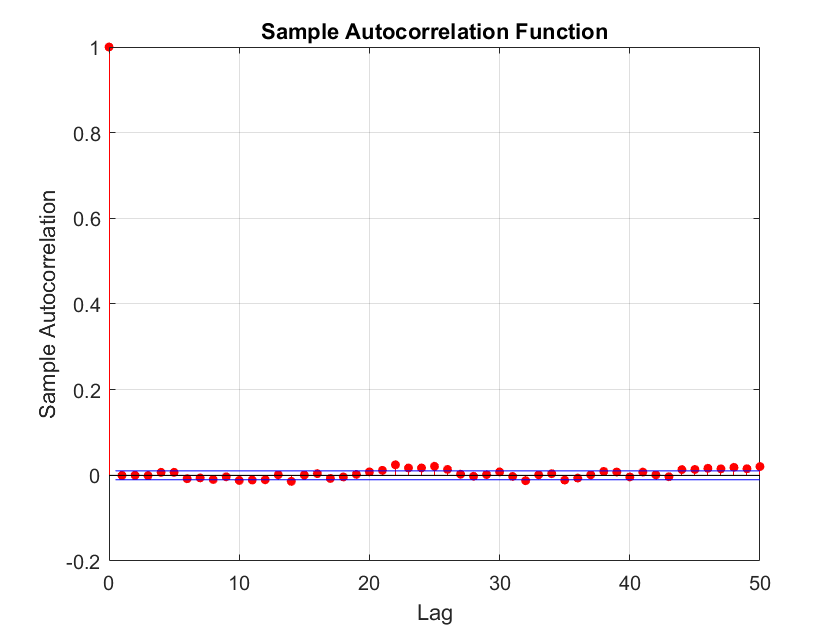

autocorr(res1,'NumLags',50)

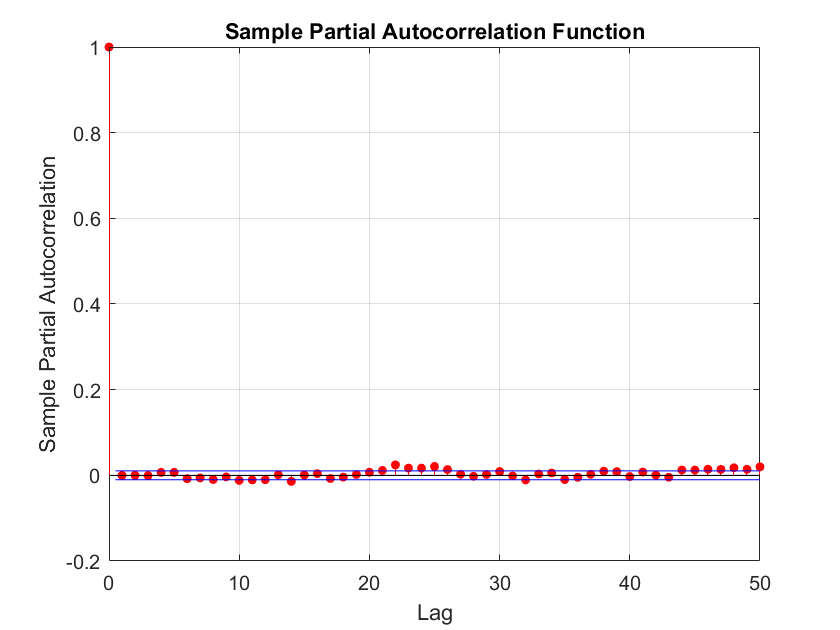

parcorr(res1,'NumLags',50)

**There are indeed meaningful values around 24 hours and 48 hours. This suggests to use a seasonal ARIMA(4,0,0)(1,0,0)12**

% Test an AR(4)(1)12
Md2 = arima('ARLags',[1, 2, 3, 4],'Seasonality',24,'SARLags',24);
EstMd2 = estimate(Md2,p)

 
    ARIMA(4,0,0) Model Seasonally Integrated with Seasonal AR(24) (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    0.00023346       0.010254       0.022769         0.98183
    AR{1}           1.0892        0.00362          300.9               0
    AR{2}         -0.18963       0.005256         -36.08     4.7473e-285
    AR{3}         0.076372      0.0056091         13.616       3.224e-42
    AR{4}        -0.043937      0.0038574         -11.39       4.687e-30
    SAR{24}       -0.49988      0.0029952        -166.89               0
    Variance        3.8402       0.017029         225.51         

EstMd2 =   arima with properties:

     Description: "ARIMA(4,0,0) Model Seasonally Integrated with Seasonal AR(24) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 52
               D: 0
               Q: 0
        Constant: 0.000233461
              AR: {1.08925 -0.189635 0.076372 -0.0439365} at lags [1 2 3 4]
             SAR: {-0.499877} at lag [24]
              MA: {}
             SMA: {}
     Seasonality: 24
            Beta: [1×0]
        Variance: 3.84021

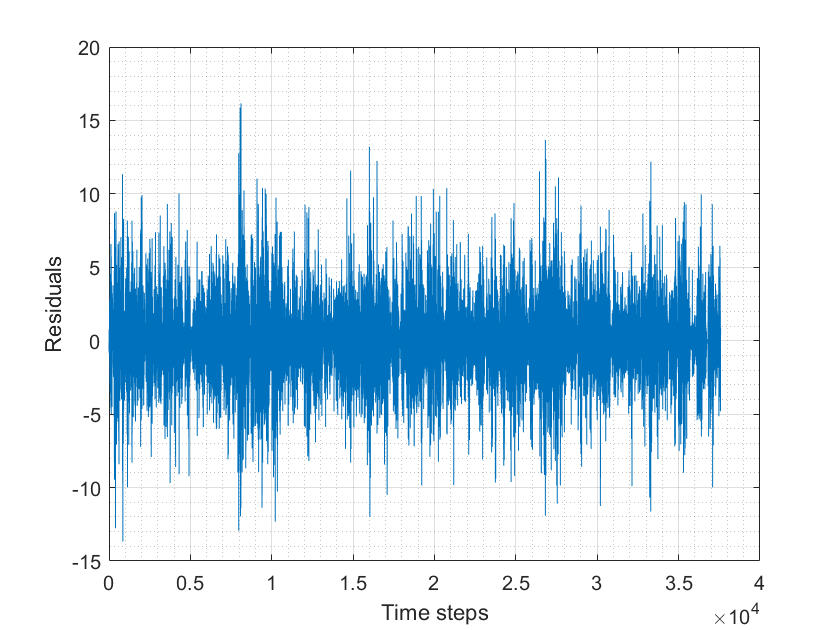

% Compute the residuals
[res2, R] = infer(EstMd2,p);
plot(res2)
grid on; grid minor;
xlabel('Time steps')
ylabel('Residuals')


% Ljung-Box test
[h,pvalues]=lbqtest(res2,'lags',[1,2,3,4,5,6,7,8,9,10])

h = 1×10 logical array
   0   0   0   0   1   1   1   1   1   1


pvalues =     0.8961    0.9865    0.9838    0.3564    0.0020    0.0042    0.0083    0.0142    0.0239    0.0112


% Validation of the hypothesis that the residuals are not correlated

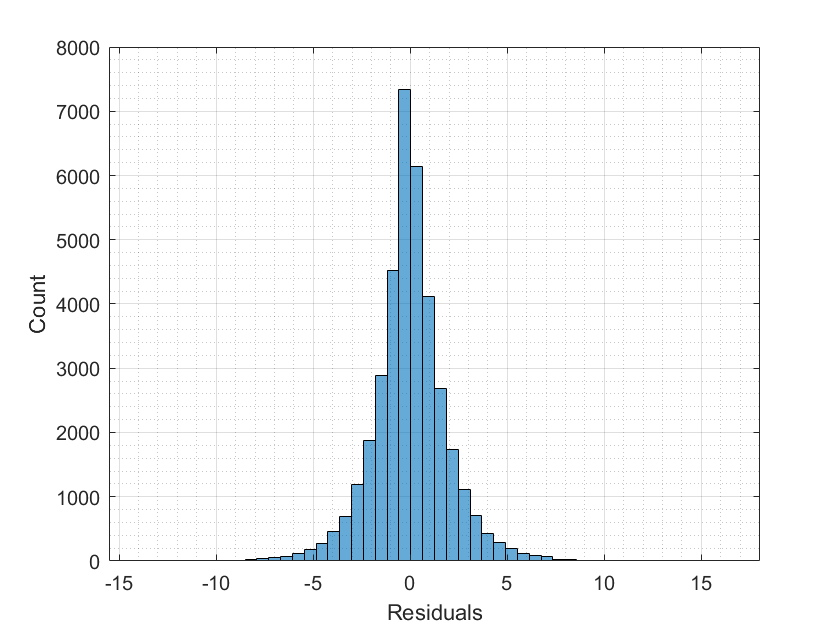

%Histogram of residuals
histogram(res2,50)
grid on; grid minor;
xlabel('Residuals')
ylabel('Count')

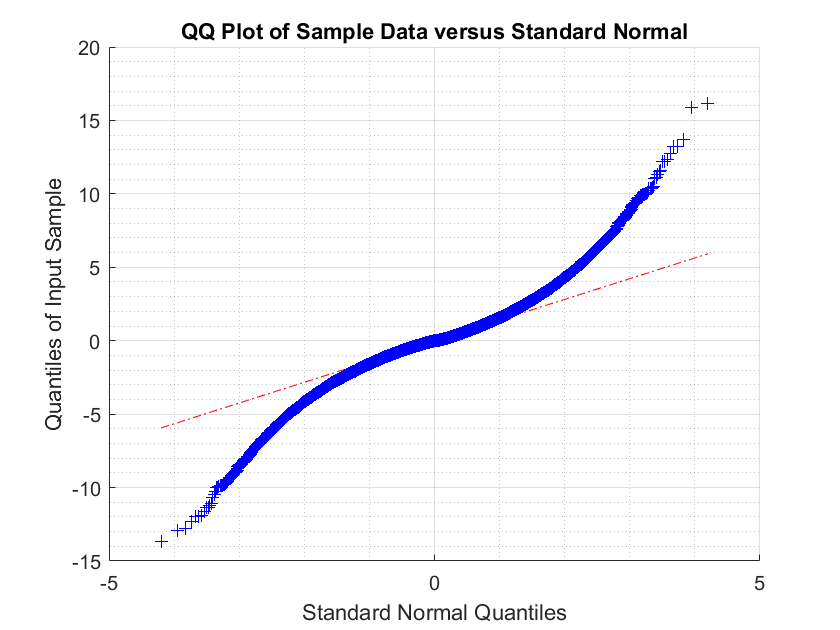


%QQ plot
qqplot(res2)
grid on; grid minor;

% Sign test
count=0;
for i=1:length(res2)-1
    if sign(res2(i)) == sign(res2(i+1))
        count = count+1;
    end
end
percent_sign_change = count/length(res2)

percent_sign_change = 0.5053


%The test sign is conclusive

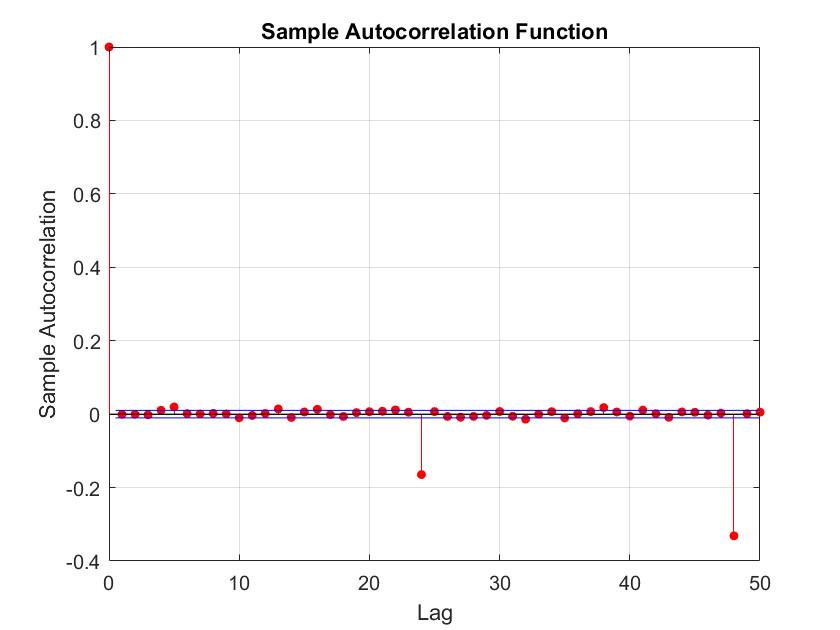

% ACF and PACF of the residuals
autocorr(res2,'NumLags',50)

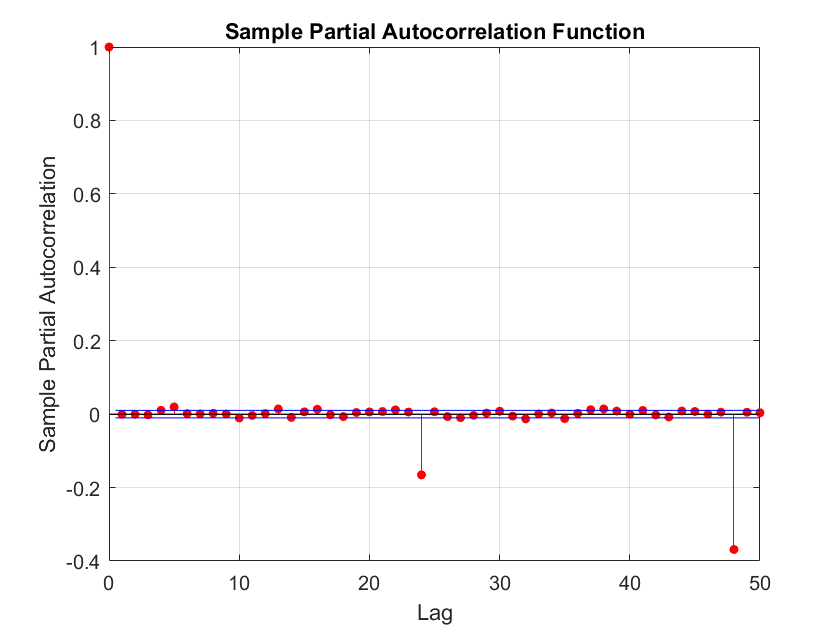

parcorr(res2,'NumLags',50)

**Looking at the ACF and PACF of the residuals it is clear that adding the seasonality does not have the expected effect. Instead of eliminating the correlations at lag 24 and 48, it created ones. **

**We may therefore stay for now with the simple AR(4) model.**

## **Predictions 1, 2 and 3 hours ahead**

% compute the errors of prediction
p_valid = p(~isnan(p));
error = zeros(length(p_valid)-7,3);
for i=4:length(p_valid)-3
    % Prediction 3h ahead given past data
    error(i-3,:) = forecast(EstMd1,3,p_valid(1:i)) - p_valid(i+1:i+3);
    if mod(i,400)==0
        X = sprintf('Compute %d%%',round(100*i/(length(p_valid)-7)));
        disp(X)
    end
end

Compute 1%
Compute 2%
Compute 3%
Compute 4%
Compute 5%
Compute 6%
Compute 7%
Compute 9%
Compute 10%
Compute 11%
Compute 12%
Compute 13%
Compute 14%
Compute 15%
Compute 16%
Compute 17%
Compute 18%
Compute 19%
Compute 20%
Compute 21%
Compute 22%
Compute 23%
Compute 24%
Compute 26%
Compute 27%
Compute 28%
Compute 29%
Compute 30%
Compute 31%
Compute 32%
Compute 33%
Compute 34%
Compute 35%
Compute 36%
Compute 37%
Compute 38%
Compute 39%
Compute 40%
Compute 42%
Compute 43%
Compute 44%
Compute 45%
Compute 46%
Compute 47%
Compute 48%
Compute 49%
Compute 50%
Compute 51%
Compute 52%
Compute 53%
Compute 54%
Compute 55%
Compute 56%
Compute 57%
Compute 59%
Compute 60%
Compute 61%
Compute 62%
Compute 63%
Compute 64%
Compute 65%
Compute 66%
Compute 67%
Compute 68%
Compute 69%
Compute 70%
Compute 71%
Compute 72%
Compute 73%
Compute 75%
Compute 76%
Compute 77%
Compute 78%
Compute 79%
Compute 80%
Compute 81%
Compute 82%
Compute 83%
Compute 84%
Compute 85%
Compute 86%
Compute 87%
Compute 88%
Compute 89%


% RMSE for each step ahead
RMSE_1h = sqrt(mean(error(:,1).^2))

RMSE_1h = 1.6171

RMSE_2h = sqrt(mean(error(:,2).^2))

RMSE_2h = 2.4125

RMSE_3h = sqrt(mean(error(:,3).^2))

RMSE_3h = 2.9378


% 95% confidence intervals
CI_1h = [RMSE_1h*norminv(0.025),RMSE_1h*norminv(0.975)]

CI_1h =    -3.1694    3.1694


CI_2h = [RMSE_2h*norminv(0.025),RMSE_2h*norminv(0.975)]

CI_2h =    -4.7284    4.7284


CI_3h = [RMSE_3h*norminv(0.025),RMSE_3h*norminv(0.975)]

CI_3h =    -5.7579    5.7579


**In comparison, with the local regression on power curve, we obtained a confidence interval of [-4.33:4.33]. Therefore, the AR(4) model improves the predictions 1h ahead, but not 2 and 3h ahead. However, it has the advantage of not requiring wind speed data.**